# KXF File Generator

*Authored by: Connor Olsen 2022*

*Edited by: Fredi Mino. 17-11-2022*

This script is used to create an adaptive Kalman filter that improves throughout a series of trials of a target touching task. 

This script looks at `TaskData.kdf` and `EventParams.txt` generated by FeedbackDecode (FBD) to determine the time interval where the Target Touching Task (TT task) takes place. 

It then assigns the targets from the TT task to the kinematics of a new `.kdf` file that can be used to train a new kalman filter in FBD.

Finally, it creates the companion .`kef` needed for FBD to use the newly generated `.kdf`

**Created by Connor Olsen**. 2022. **All rights reserved** and copyright stuff :)

## Step 0: Clear the workspace

clear kxf_file_generator;
clc;
close all;
tic

## Step 1: Select the Data Directory and Retrieve Relevant Files

Insert the name of the folder where the `TaskData.kdf` file is located and retrieve `TaskData.kdf` and `EventParams.txt`

directory = "D:\FeedbackDecode\20230117-142654"
;

files = string(ls(directory));
l_array = contains(files, "TaskData");
files = files(l_array);
l_array = contains(files, ".kdf");
files = files(l_array);
if length(files) > 1
    error("Too many TaskData files!");
end
task_file = convertStringsToChars(strtrim(strcat(directory, "\", files)));

files = string(ls(directory));
l_array = contains(files, "EventParams");
files = files(l_array);
l_array = contains(files, ".txt");
files = files(l_array);
if length(files) > 1
    error("Too many EventParam files!");
end
events_file = convertStringsToChars(strtrim(strcat(directory, "\", files)));

## Step 2: Read and Visualize the Files

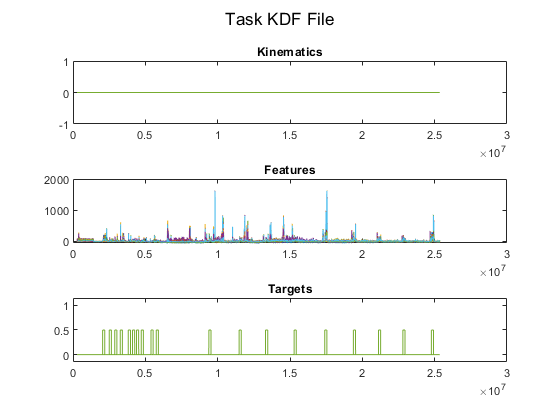

% MAKE SURE TO PROVIDE THE ABSOLUTE PATH OF THE FOLDER BEING OPERATED
% THE NEW .KDF FILE WILL BE SAVED IN AS MetaDynamicTraining_#.kdf, where
% the number increases depending on the number of Target Touching Task
% sessions have been performed

[kinematics, features, targets, kalman, nip] = readKDF(task_file);
[TrialStruct, EventStruct] = readEventParamsFile(events_file);

figure();

ax1 = subplot(3, 1, 1);
plot(nip, kinematics');
title("Kinematics")

ax3 = subplot(3, 1, 2);
plot(nip, features');
title("Features");

ax2 = subplot(3,1,3);
plot(nip, targets');
title("Targets")
ylim([-0.15 1.15])

% isolates the trial windows
task_starts = [EventStruct.EnableStartTrials.NIPTime];
task_stops = [EventStruct.DisableStartTrials.NIPTime];

% removes excess trial start windows
while length(task_starts) > length(task_stops)
    task_starts = task_starts(2:end);
end

% Adjusts length of windows to be just a bit bigger
for i = 1:length(task_starts)
    task_starts(i) = nip(find(nip == task_starts(i)) - 75);
    task_stops(i) = nip(find(nip == task_stops(i)) + 50);
end

%Add label lines to show where KDF will be cropped
% xline(startsTTT, '-', 'Trial St  art')
% xline(stopsTTT,'-', 'Trial End');

linkaxes([ax1, ax2, ax3],'x');
sgtitle("Task KDF File")

## Step 3: Determine TT Task Intervals

%% Crop the Time to the starts and stops of the trainings.
IndexToKeep = and(nip > task_starts(1),nip < task_stops(1));

if length(task_stops) > 1
    for i = 2:length(task_stops)
        IndexToKeep = or(IndexToKeep, and(nip > task_starts(i),nip < task_stops(i)));
    end
end
kinematics = SmoothingFilter(targets(:,IndexToKeep)', 4)';
features = features(:, IndexToKeep);
targets = targets(:, IndexToKeep);
kalman = kalman(:, IndexToKeep);
nip = nip(IndexToKeep);

## Step 4: Generate and Check the New KDF File

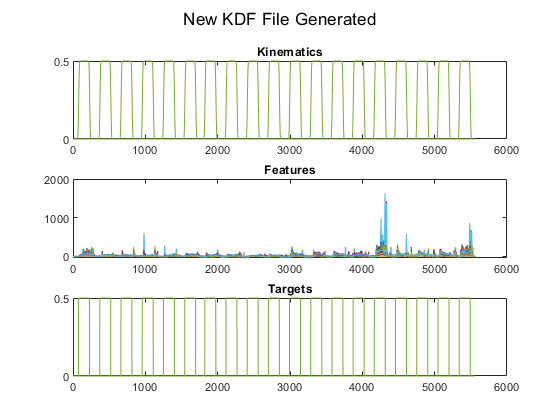

filename = sprintf("TrainingData_MetaDynamicTraining_%d.kdf", length(task_stops));
kdfFile = fullfile(directory,filename);
kdfFID = fopen(kdfFile, 'w+');
fwrite(kdfFID,[1;720;12;12;12],'single'); %writing header
for i = 1:length(nip)
    fwrite(kdfFID,[nip(i);features(:,i);kinematics(:,i);targets(:,i);kalman(:, i)],'single'); %Saving data to ftraining file.
end
fclose(kdfFID);
 
%% Check the newly Generated KDF File
[k, f, t, ~, n] = readKDF(kdfFile);

figure();
subplot(311);plot(k');title("Kinematics");
subplot(312);plot(f');title("Features");
subplot(313);plot(t');title("Targets");
sgtitle("New KDF File Generated");

## Step 5: Generate KEF File

%% Generate KEF File
l_array = logical(k);
condensed = logical(sum(l_array));

starts = [];
stops = [];
extendedStarts = [];
extendedStops = [];

for i = 1:length(condensed)-1
    if condensed(i) == 0 && condensed(i+1) == 1
        starts = [starts, n(i)];
        extendedStarts = [extendedStarts, n(i-15)];
    elseif condensed(i) == 1 && condensed(i+1) == 0
        stops = [stops, n(i)];
        extendedStops = [extendedStops, n(i+15)];
    end
end
% Find the starts and stops
if length(starts) ~= length(stops)
    error("Number of Starts Doesn't Equal Number of Stops")
end

for i = 1:length(starts)
    i1 = find(n == starts(i));
    i2 = find(n == stops(i));
    for j = 1:12
        amplitudes(j,i) = max(k(j,i1:i2));
    end
end

filename = sprintf("TrainingData_MetaDynamicTraining_%d.kef", length(task_stops));
kefFile = fullfile(directory, filename);
kefFID = fopen(kefFile, 'w+');

for i = 1:length(starts)
fwrite(kefFID,sprintf("SS.TargOnTS=%d;SS.TrialTS=%d;SS.MvntMat=[" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "%.02f,%.02f,%.02f,%.02f,;" + ...
    "];\n", extendedStarts(i),extendedStops(i), ...
0, 0, amplitudes(1,i), 0, ...
0, 0, amplitudes(2,i), 0, ...
0, 0, amplitudes(3,i), 0, ...
0, 0, amplitudes(4,i), 0, ...
0, 0, amplitudes(5,i), 0, ...
0, 0, amplitudes(6,i), 0, ...
0, 0, amplitudes(7,i), 0, ...
0, 0, amplitudes(8,i), 0, ...
0, 0, amplitudes(9,i), 0, ...
0, 0, amplitudes(10,i), 0, ...
0, 0, amplitudes(11,i), 0, ...
0, 0, amplitudes(12,i), 0 ...
));
end
fclose(kefFID);
disp(toc)

   12.0892

